# Practical 1: Model Predictive Control

Author: Cameron  Stroud

Student Number: n11552123

## Learning Outcomes:

In this practical you will address the following Learning Outcomes:

- Optimal Control with Cost Functions

- Predictive Control

- System and Input Constraints

clear; close all; clc
set(0,'DefaultFigureWindowStyle','docked')

## Background

In this practical we will consider a hanging load from a gantry crane. The position of the crane block can be controlled via a motor on the crane track which can push or pull the block with at most 100N of force. The crane block is rated to travel at a maximum of 3 m/s in both direction. As force is applied to the block the load hanging from the crane will also move. For simplicity we model the hanging chain and object as a solid rod. The crane track is 12 m long, where the containers on the dock are 2m from the track end and the ship loading point is 2m from the track end over the water. The goal is to move the cart to over the ship to unload a container within 10 seconds.

The dynamics of the crane cart block and hanging object can be described by the following linearised continuous-time state space model:


$$\dot{x} = \left[ \matrix{0 & 1 & 0 & 0 \cr
    0 & \frac{b*(m*l^2 - I)}{I*(M+m)-M*m*l^2} & \frac{-m^2*l^2*g}{I*(M+m)-M*m*l^2}  & 0 \cr
    0 & 0 & 0 & 1 \cr
    0 & \frac{-b*m*l}{I*(M+m)-M*m*l^2} & \frac{m*g*l*(M+m)}{I*(M+m)-M*m*l^2} & 0} \right] x
+ \left[\matrix{ 0 \cr
    \frac{I-m*l^2}{I*(M+m)-M*m*l^2} \cr
    0 \cr
    \frac{m*l}{I*(M+m)-M*m*l^2} } \right] u$$


where $x^T = [p, ~ v, ~ \theta, ~ \omega ]$ is the state and $p$ is the block position, $v$ is the block velocity, $\theta$ is the load rod angle, $\omega$ is the load angular rate, and the control action is $u$. This linearisation is around the angle and is valid for small deviations from the equilibrium. The parameters are: $M$ block mass, $m$ rod mass, $I$ rod inertia, $l$ rod length, $b$ block friction, and $g$ gravity.

For safety, the object attached at the end of the crane should swing no more than 10 degrees in either direction with no more than 50 deg/s.

## Question 1: Reference and Constraint Design

Assume that the crane starts at rest above the containers on the dock. Identify:

- any state or control constraints,

- the goal, and

- initial condition.

State constraints:

    $0 \leq p \leq 12$ absolute limit, $2 \leq p \leq 10$ operation limit 

    
$$0 \leq v \leq 3$$


   
$$-10 \leq\theta\leq 10$$


   
$$-50 \leq\omega\leq 50$$


Control constraints:

    $\pm 100$N force

Goal:

    $p
$ is 2m from track end, $\therefore p=10$,

    $v = 0$, at rest

    $\theta = 0$, no sway angle

    $\omega = 0$, no sway

    $\therefore x_f^T=[10, 0, 0, 0]$,

    
$$t_f \leq 10
$$


Initial condition:

    $x^T=[2, 0, 0, 0]$, $u^T=[0, 0, 0, 0]$  $\therefore \dot{x}(0) = [0, 0, 0, 0]$

### Code Implementation and Conversion to Discrete-time

We convert our dynamics to discrete-time as digitial controllers are typically implemented in discrete-time.

Using a sampling rate of $T_s$ seconds per sample, we can write the dynamics in the form


$$x_{k+1} = A x_k + B u_k$$


where $k$ is the discrete-time index giving the state $x_k = x(k T_s)$ and control $u_k = u(k T_s)$.

% Set Parameters
M = 0.5; % block mass
m = 0.2; % rod mass
l = 0.3; % rod length
I = 0.006; % rod inertia
b = 0.2; % block friction
g = 9.81; % gravity

% Create continuous-time dynamics
Ac = [0 1 0 0;
    0 b*(m*l^2 - I)/(I*(M+m)-M*m*l^2) -m^2*l^2*g/(I*(M+m)-M*m*l^2) 0;
    0 0 0 1;
    0 -b*m*l/(I*(M+m)-M*m*l^2) m*g*l*(M+m)/(I*(M+m)-M*m*l^2) 0];

Bc = [0;
    (I-m*l^2)/(I*(M+m)-M*m*l^2);
    0;
    m*l/(I*(M+m)-M*m*l^2)];

% Convert to Discrete-time
Ts = 0.1; % seconds per sample

ABdisc = expm([Ac Bc; zeros(1,5)]*Ts);
A = ABdisc(1:4,1:4);
B = ABdisc(1:4,end);

% Set the initial condition
x0 = [2, 0, 0, 0]

x0 =      2     0     0     0



% Set the target position
xstar = [10, 0, 0, 0]

xstar =     10     0     0     0


## Optimal Control Cost Function

Let us now write an infinite horizon optimal control cost function to penalise the error between the state and desired reference and the control action.

Consider a quadratic function in the form of


$$J(x_k, \vec{u}) = \sum_{\ell=0}^\infty (x_{k+\ell|k} - x^\star)^{T} Q (x_{k+\ell|k} - x^\star) + u_{k+\ell|k}^{T} R u_{k+\ell|k}$$


with $Q$, $R$ matrices of approrpriate sizes that weight on the state and control action, respectively, and $x^\star$ a reference vector.

## Question 2: Cost Function Choices

Propose cost function weights. Consider both the goal and the constraints.

Explain your choices.

As Q pertains to the state space, we select weightings based on the emphasis we desire on the controlled state. For the most part, each cost is equally desirable to meet the criteria and set it as 1, however, we set q2 to be 2 in order to penalise the velocity aspect higher to keep it within the relatively tight bounds. Likewise, with R, we simply set it to 1, as the base control action penalty should be sufficient.

% Cost function weights
%% Q
q1 = 1;
q2 = 2;
q3 = 1;
q4 = 1;
q_vec = [q1 q2 q3 q4];
Q = diag(q_vec);
%% R
R = 1;

% set sim time
Tfinal_sec = 20; % sec

### LQR Simulation

% compute Discrete-time LQR gain
K = dlqr(A,B,Q,R);

% convert simulation time to samples
Tfinal = ceil(Tfinal_sec/Ts); % samples
% round up to the nearest full sample

% create time vector
time = 0:Ts:(Tfinal-1)*Ts;

% preallocate
x = zeros(4,Tfinal);
u = zeros(1,Tfinal);

% Simulate LQR
x(:,1) = x0; % set the first state to the initial state value
for kk = 1:Tfinal-1
    u(kk) = -K*(x(:,kk) - xstar'); % compute the control gain
    x(:,kk+1) = A*x(:,kk) + B*u(kk); % propagate the state
end

% plot
figure
plot(time,x(1,:))

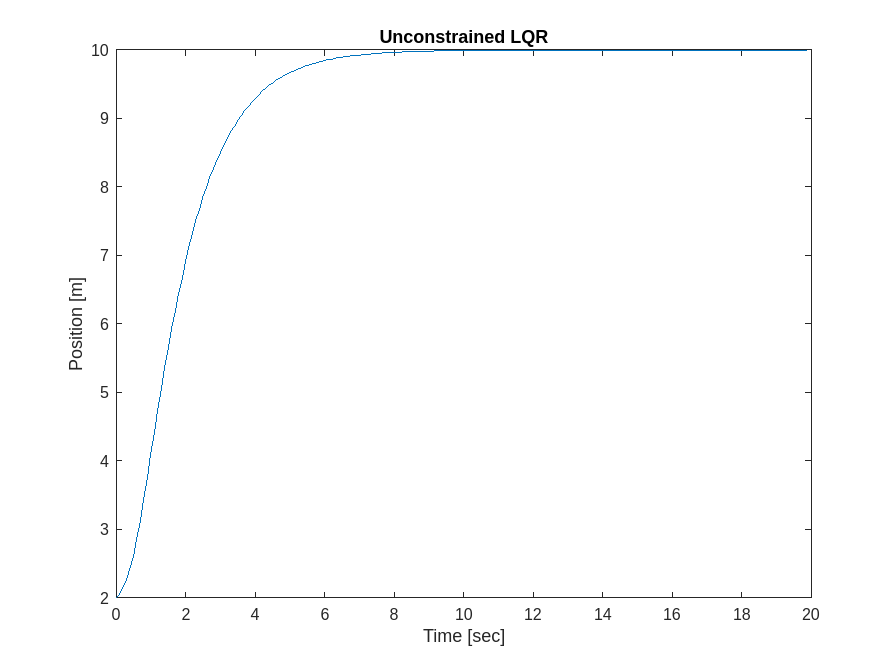

xlabel('Time [sec]'); ylabel('Position [m]'); title('Unconstrained LQR')

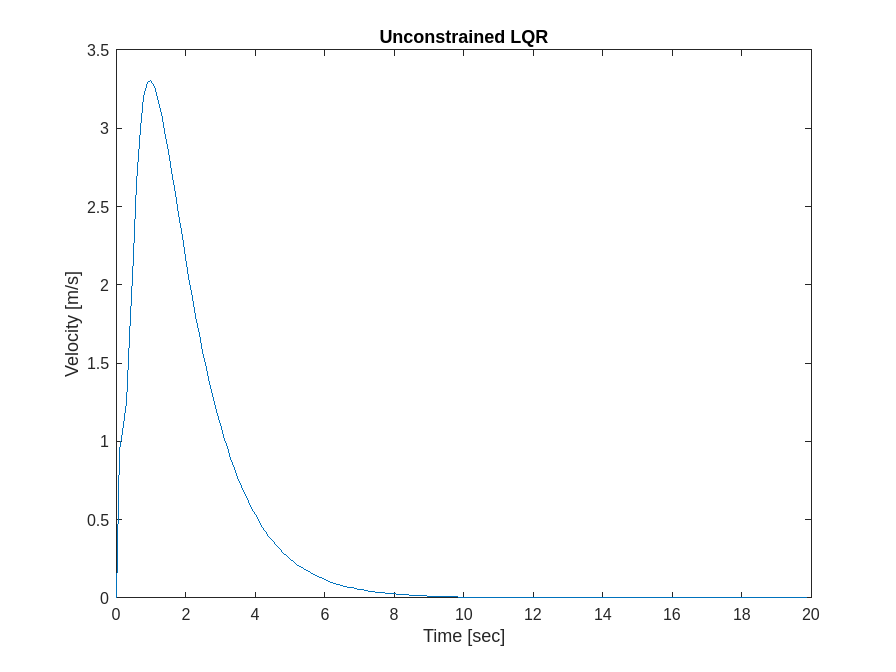

figure
plot(time,x(2,:))
xlabel('Time [sec]'); ylabel('Velocity [m/s]'); title('Unconstrained LQR')

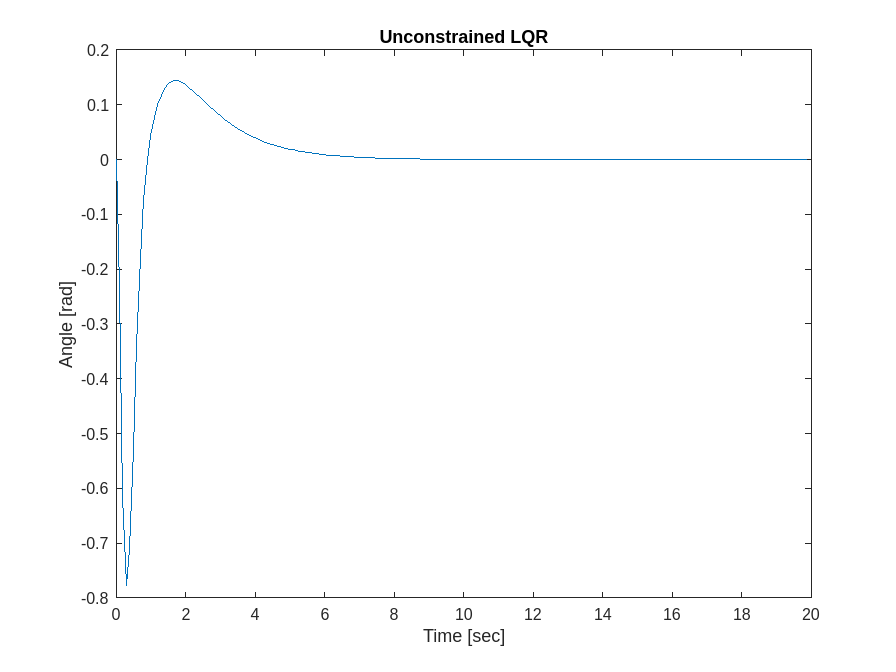

figure
plot(time,x(3,:))
xlabel('Time [sec]'); ylabel('Angle [rad]'); title('Unconstrained LQR')

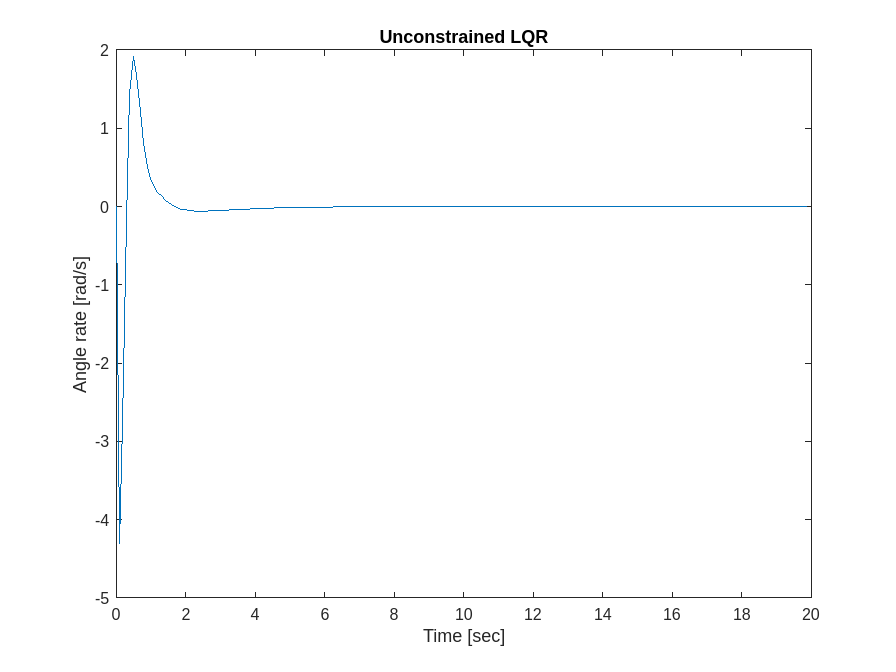

figure
plot(time,x(4,:))
xlabel('Time [sec]'); ylabel('Angle rate [rad/s]'); title('Unconstrained LQR')

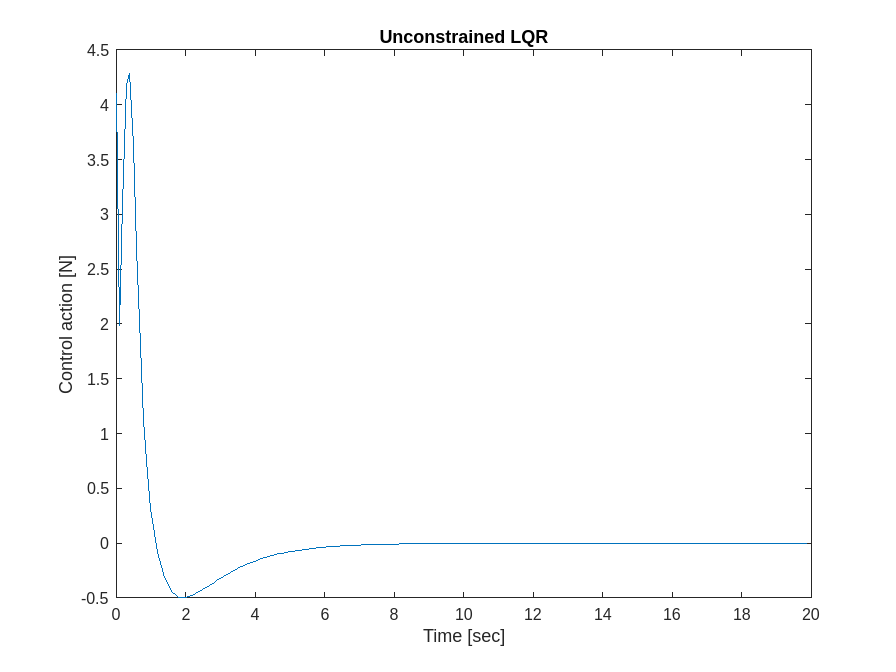

figure
plot(time,u)
xlabel('Time [sec]'); ylabel('Control action [N]'); title('Unconstrained LQR')

## **Question 3: Cost Function Design**

Consider different state and control cost choices.

**How do different choices impact on the feedback control performance?**

**Design your cost function to meet the state and control constraints. Is the resulting performance appropriate?**

**Use figures of the state trajectory to illustrate the differences.**

Increasing R results in higher penalty control action, reducing the difference from state-to-state. With R=1, it shares the same penalty as Q, and the velocity overshoots the constraint of 3m/s. By applying a larger R, there is a larger penalty for control action which reduces the peak velocity, but results in a slower convergence to the target state.

By setting the individual elements of Q, we can impose finer control of the state error. As all the other states remain within their bounds, we can alter just $q_2$ in order to penalise it further and keep it within the constraints. The following was used to achieve the goal without violating the constraints.

$Q = \left[ \matrix{1 & 0 & 0 & 0 \cr    0 & 2 & 0  & 0 \cr    0 & 0 & 1 & 0 \cr    0 & 0 & 0 & 1} \right]$, R=1

## Question 4: Analysis

**Inspect your state figures, discuss any performance issues.**

**How could you ensure that the constraints are met?**

The velocity term exceeds the maximum velocity described by the problem by a small margin. One way to ensure the constraints are met is to tune the Q and R values to achieve the desired goal, but a more effective way would be to incorporate the constraints into the cost function, which we can do by applying MPC.

## Model Predictive Control

We now refine our infinite horizon cost function into a finite horizon cost function using the state and control action costs from above as inspiration, and directly include the constraints. In a finite horizon setting we achieve infinite horizon operation by using the receeding horizon principle. This leads to Model Predictive Control.

## Question 5: Design Analysis

Explore how to improve the performance of the control design now using constrained Model Predictive Control. Consider different stage costs, constraints, and time horizon length. You will need to choose the cost function weights, prediction horizon, and constraint vectors.

Comment on any computational impacts of your choices.

% set new cost function weights
Q = diag([1 1 1 1]);
R = 1;

% set the simulation time
TfinalMPC_sec = 20;
% convert to discrete-time steps
TfinalMPC = ceil(TfinalMPC_sec/Ts); % round up to nearest full step

% Create simulation time
timeMPC = 0:Ts:(TfinalMPC-1)*Ts;
% set the prediction horizon in seconds
N_sec = Ts * 3;
% convert to discrete-time steps
N = ceil(N_sec/Ts); 

% Create Prediction Horizon Model and Cost
Delta = A;
Phitemp = B;
Phi = B;
Qbar = Q;
Rbar = R;
for ii = 2:N
    Delta = [A; Delta*A];
    Phitemp = [A*Phitemp B];
    Phi = [Phi zeros(4*(ii-1),1); Phitemp];
    Qbar = blkdiag(Qbar, Q);
    Rbar = blkdiag(Rbar, R);
end


% Fixed Hession
H = 2 * (Phi.'*Qbar*Phi + Rbar);


% Set the equality constraints to null
Aeq = zeros(0,length(H));
Beq = zeros(0,1);

% Set the inequality constraints
xmin = [2 0 deg2rad(-10) deg2rad(-50)]';
xmax = [10 3 deg2rad(10) deg2rad(50)]';
umin = [0 0 0 0]';
umax = [100 100 100 100]';

% propagate the constant target reference and constraints across the horizon
xstar = xstar';
xstarbig = kron(ones(N,1),xstar);
xmin = kron(ones(N,1),xmin);
xmax = kron(ones(N,1),xmax);
umin = kron(ones(N,1),umin);
umax = kron(ones(N,1),umax);

% Create the inequality constraint matrix
Ain = [-Phi;Phi;-eye(N);eye(N)];

% set the initial constraints to 'inactive'
iA = false(size(Ain,1),1);


% set the MPC Iterations to a large number
opt = mpcActiveSetOptions;
% opt.MaxIterations = 10000; % If exitflag == 0 increase this value

% preallocate
xMPC = zeros(4,TfinalMPC);
uMPC = zeros(1,TfinalMPC);

% Simulate MPC
xMPC(:,1) = x0; % set the first state to the initial state value
tic
for kk = 1:TfinalMPC-1
    % create latest inequality constraint vector
    Bin = [Delta*xMPC(:,kk) - xmin;
        xmax - Delta*xMPC(:,kk);-umin;umax];
    % create 'Multiplier of the objective function linear term'
    fT = 2*(Phi).'*Qbar*(Delta*xMPC(:,kk) - xstarbig);

    % SOLVE MPC using a quadratic program solver
    size(H)
    [uMPCout, exitflag, iA, lambda] = mpcActiveSetSolver...
        (H, fT, Ain, Bin, Aeq, Beq, iA, opt);
    
    % Exitflag: >0 is number of iterations for successful solve,
    %            0 max iterations reached,
    %           -1 indicates problem is infeasible, and
    %           -2 indicates numeric error.
    if exitflag == -2 || exitflag == -1 || exitflag == 0
        error(['MPC exitflag = ' num2str(exitflag)])
    end
    
    % extract the current control action as the first element of the
    % control prediction from the MPC
    uMPC(kk) = uMPCout(1);

    % propagate system
    xMPC(:,kk+1) = A*xMPC(:,kk) + B*uMPC(kk);
end

ans =      4     4


Error using mpcActiveSetSolver
Expected b to be an array with number of rows equal to 40.

Error in mpcActiveSetSolver (line 154)
    validateattributes(b,{'numeric'},{'real','finite','column','nrows',m},'mpcActiveSetSolver','b');

toc


% plot
figure
plot(timeMPC,xMPC(1,:))
xlabel('Time [sec]'); ylabel('Position [m]'); title('Constrained MPC')
figure
plot(timeMPC,xMPC(2,:))
xlabel('Time [sec]'); ylabel('Velocity [m/s]'); title('Constrained MPC')
figure
plot(timeMPC,xMPC(3,:))
xlabel('Time [sec]'); ylabel('Angle [rad]'); title('Constrained MPC')
figure
plot(timeMPC,xMPC(4,:))
xlabel('Time [sec]'); ylabel('Angle rate [rad/s]'); title('Constrained MPC')
figure
plot(timeMPC,uMPC)
xlabel('Time [sec]'); ylabel('Control action [N]'); title('Constrained MPC')

## Question 6: LQR vs MPC

Discuss the differences between LQR and MPC.

MPC enables direct application of constraints to the cost function.

## Question 7: Discussion

Does the inclusion of state constraints resolve the issues identified for the LQR design? 

Unknown